依赖[统一实验分析作图v18.0.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases/tag/v17.1.0)

将每只小鼠的hit/miss 比例与template cell 在hit/miss trial中的活动平均强度进行线性拟合

DataSet=TransferLearning.FullCalcium;
CalciumBehavior=groupsummary(unique(DataSet.TableQuery(["TrialUID","Mouse","Behavior"],Phase="Transfer",Stimulus="AudioWater",Paradigm="光声",ZLayer=["MOp2/3","MOp5"],Behavior=[0,1])),'Mouse','mean','Behavior');

QueryTable=UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'HitMissLinearFitting');
QueryTable.CellUID(:)={TransferLearning.TemplateCellUID(0.05)};
HitMissCalcium=UniExp.NtatsCellReplenish(DataSet.QueryNTATS(QueryTable,UniExp.Flags.log2FdF0,1:24,UniExp.Flags.Median));

[~,Index]=ismember(HitMissCalcium.CellUID,DataSet.Cells.CellUID);
HitMissCalcium.Mouse=DataSet.Cells.Mouse(Index);

Fitting=groupsummary(HitMissCalcium,'Mouse','mean','NTATS');
Fitting.mean_NTATS=sum(Fitting.mean_NTATS(:,24:32,:),2);
Fitting.HitMinusMiss=Fitting.mean_NTATS.Transfer_audio_water_hit-Fitting.mean_NTATS.Transfer_audio_water_miss;
Fitting.HitDivideMiss=Fitting.mean_NTATS.Transfer_audio_water_hit./Fitting.mean_NTATS.Transfer_audio_water_miss;
[~,Index]=ismember(Fitting.Mouse,CalciumBehavior.Mouse);
Fitting.Performance=CalciumBehavior.mean_Behavior(Index);

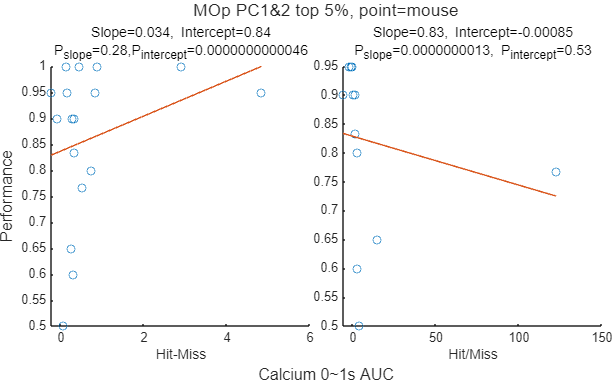

figure;
Layout=tiledlayout(1,2,TileSpacing='tight',Padding='tight');
nexttile;
scatter(Fitting.HitMinusMiss,Fitting.Performance);
[X2,Y2,Coefficients]=TransferLearning.PolyFitLine(Fitting.HitMinusMiss,Fitting.Performance);
line(X2,Y2);
Coefficients=num2cell(MATLAB.SignificantFixedpoint(Coefficients{["x1","(Intercept)"],["Estimate","pValue"]},2));
title(sprintf('Slope=%s, Intercept=%s\nP_{slope}=%s,P_{intercept}=%s',Coefficients{:}));
xlabel('Hit-Miss');
nexttile;
NonInf=~isinf(Fitting.HitDivideMiss);
Xs=Fitting.HitDivideMiss(NonInf);
Ys=Fitting.Performance(NonInf);
scatter(Xs,Ys);
[X2,Y2,Coefficients]=TransferLearning.PolyFitLine(Xs,Ys);
line(X2,Y2);
Coefficients=num2cell(MATLAB.SignificantFixedpoint(Coefficients{:,["Estimate","pValue"]},2));
title(sprintf('Slope=%s, Intercept=%s\nP_{slope}=%s, P_{intercept}=%s',Coefficients{:}));
xlabel('Hit/Miss');
ylabel(Layout,'Performance');
xlabel(Layout,'Calcium 0~1s AUC');
title(Layout,'MOp PC1&2 top 5%, point=mouse');
MATLAB.Graphics.FigureAspectRatio(8,5,1);
print(TransferLearning.ProjectPath('HitMissLinearFitting.svg'),'-dsvg');